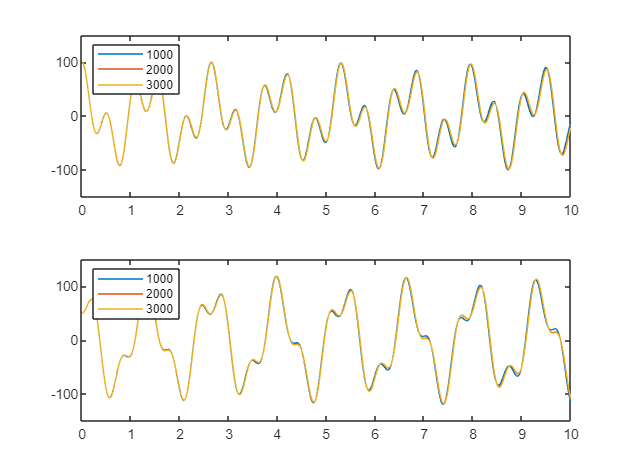

T = 10;

k1 = 4.66;
k2 = 4.66;
m1 = 0.0917;
m2 = 0.0765;

x10 = 100;
x20 = 50;
x1p0 = 0;
x2p0 = 0;

A = [0, 1, 0, 0;
    -1*(k1+k2)/m1, 0, k2/m1, 0;
    0, 0, 0, 1;
    k2/m2, 0, -1*k2/m2, 0];

Ns = [1000, 2000, 3000];

figure;

subplot(2, 1, 1);
for N = Ns
    [t, x1, x1p, x2, x2p] = IEMsolver(A, x10, x1p0, x20, x2p0, T, N);
    plot(t, x1);
    hold on;
end

legend(string(Ns), location="northwest");
ylim([-150, 150]);

subplot(2, 1, 2);
for N = Ns
    [t, x1, x1p, x2, x2p] = IEMsolver(A, x10, x1p0, x20, x2p0, T, N);
    plot(t, x2);
    hold on;
end

legend(string(Ns), location="northwest");
ylim([-150, 150]);

function [t, x1, x1p, x2, x2p] = IEMsolver(A, x10, x1p0, x20, x2p0, T, N)
    dt = T/N;
    t = 0:dt:T;

    SOL = nan(4, length(t));
    SOL(1, 1) = x10;
    SOL(2, 1) = x1p0;
    SOL(3, 1) = x20;
    SOL(4, 1) = x2p0;

    for i = 2:length(t)
        zn = SOL(:, i-1);
        SL = A*zn;
        SR = A*(zn + dt*SL);
        SOL(:, i) = zn + (dt/2)*(SL+SR);
    end

    x1 = SOL(1, :);
    x1p = SOL(2, :);
    x2 = SOL(3, :);
    x2p = SOL(4, :);
end